## [**Waves and disorder**](https://chaos.if.uj.edu.pl/~delande/Lectures/)

### Lectures on Waves in disordered media: transport and localization

#### [Classical diffusive dynamics - Lectures on Waves in disordered media: transport and localization](https://chaos.if.uj.edu.pl/~delande/Lectures/?classical-diffusive-dynamics,17)

#### *Classical propagation in a random 2D potential*

该脚本计算了二维随机势场中粒子的经典传播过程。每条轨迹通过数值积分牛顿方程得到。初始点在原点，初始传播方向随机。初始速度根据所有轨迹具有相同总能量计算。脚本会在"propagation_time"时间内推进"number_of_trajectories"条轨迹。无序势场由若干高斯势（标准差 sigma=1）叠加而成，每个高斯势的最大值在正态分布（sigma=1）中随机选取，位置也在边长为"system_size"的正方形内随机分布，密度为"density_of_scatterers"。

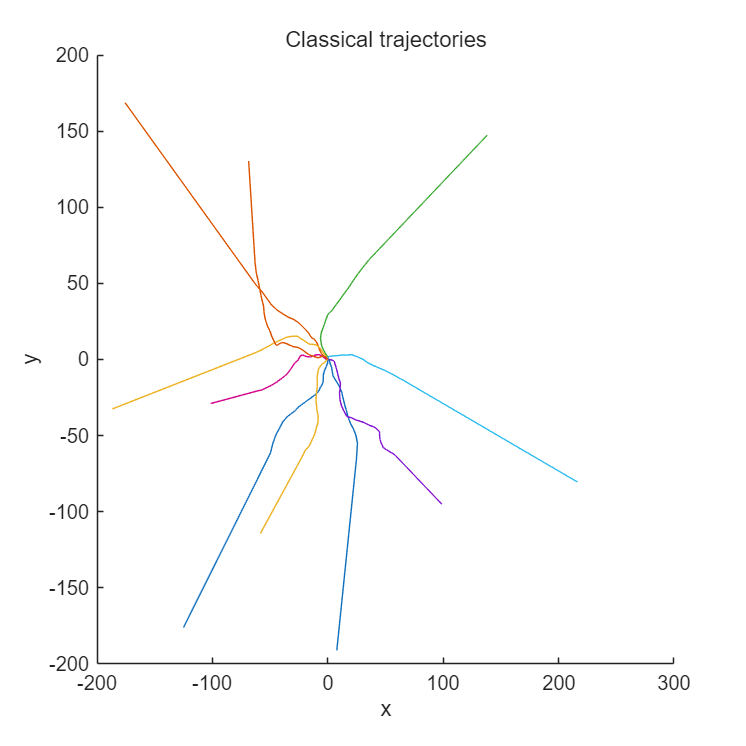

% 参数设置
propagation_time = 40;
density_of_scatterers = 0.5;
system_size = 120;
energy = 1;
number_of_trajectories = 1000;

time_step = 1.0;
number_of_bins = 50;
number_of_pixels_for_potential = 100;
number_of_printed_trajectories = 10;

number_of_times = round(propagation_time / time_step);
number_of_scatterers = round(density_of_scatterers * system_size^2);
histogram_bin = system_size / number_of_bins;
half_system_size = 0.5 * system_size;
limit = half_system_size - 1.0;

histogram_x = zeros(number_of_bins, 1);
histogram_y = zeros(number_of_bins, 1);
r2 = zeros(number_of_times+1, 1);

% 预分配轨迹
all_x = zeros(number_of_times+1, number_of_printed_trajectories);
all_y = zeros(number_of_times+1, number_of_printed_trajectories);

% 向量化生成所有势场参数
scatterer_position_x = rand(number_of_trajectories, number_of_scatterers) * 2 * half_system_size - half_system_size;
scatterer_position_y = rand(number_of_trajectories, number_of_scatterers) * 2 * half_system_size - half_system_size;
scatterer_amplitude  = randn(number_of_trajectories, number_of_scatterers);

% 初始点势能
pot0 = sum(scatterer_amplitude .* exp(-0.5 * (scatterer_position_x.^2 + scatterer_position_y.^2)), 2);

% 保证所有势能小于能量
valid = pot0 < energy;
while any(~valid)
    scatterer_position_x(~valid, :) = rand(sum(~valid), number_of_scatterers) * 2 * half_system_size - half_system_size;
    scatterer_position_y(~valid, :) = rand(sum(~valid), number_of_scatterers) * 2 * half_system_size - half_system_size;
    scatterer_amplitude(~valid, :)  = randn(sum(~valid), number_of_scatterers);
    pot0(~valid) = sum(scatterer_amplitude(~valid, :) .* exp(-0.5 * (scatterer_position_x(~valid, :).^2 + scatterer_position_y(~valid, :).^2)), 2);
    valid = pot0 < energy;
end

% 初始速度和方向
v0 = sqrt(2 * (energy - pot0));
angle = rand(number_of_trajectories, 1) * 2 * pi;
y = zeros(number_of_times+1, 4, number_of_trajectories); % [x, y, vx, vy]
y(1, 1, :) = 0;
y(1, 2, :) = 0;
y(1, 3, :) = v0 .* cos(angle);
y(1, 4, :) = v0 .* sin(angle);

% 轨迹推进（向量化）
for i_times = 1:number_of_times
    x_now = squeeze(y(i_times, 1, :));
    y_now = squeeze(y(i_times, 2, :));
    vx_now = squeeze(y(i_times, 3, :));
    vy_now = squeeze(y(i_times, 4, :));
    % 计算力（向量化）
    dx = x_now - scatterer_position_x;
    dy = y_now - scatterer_position_y;
    exp_term = exp(-0.5 * (dx.^2 + dy.^2));
    fx = sum(dx .* scatterer_amplitude .* exp_term, 2);
    fy = sum(dy .* scatterer_amplitude .* exp_term, 2);
    % 更新
    y(i_times+1, 1, :) = x_now + vx_now * time_step;
    y(i_times+1, 2, :) = y_now + vy_now * time_step;
    y(i_times+1, 3, :) = vx_now + fx * time_step;
    y(i_times+1, 4, :) = vy_now + fy * time_step;
    % 均方位移
    r2(i_times+1) = r2(i_times+1) + mean(y(i_times+1, 1, :).^2 + y(i_times+1, 2, :).^2);
    
end

% 轨迹作图（前 number_of_printed_trajectories 条）
figure; hold on;
for j = 1:number_of_printed_trajectories
    plot(squeeze(y(:, 1, j)), squeeze(y(:, 2, j)));
    % pause(0.01)
end
xlabel('x'); ylabel('y'); title('Classical trajectories');
hold off;

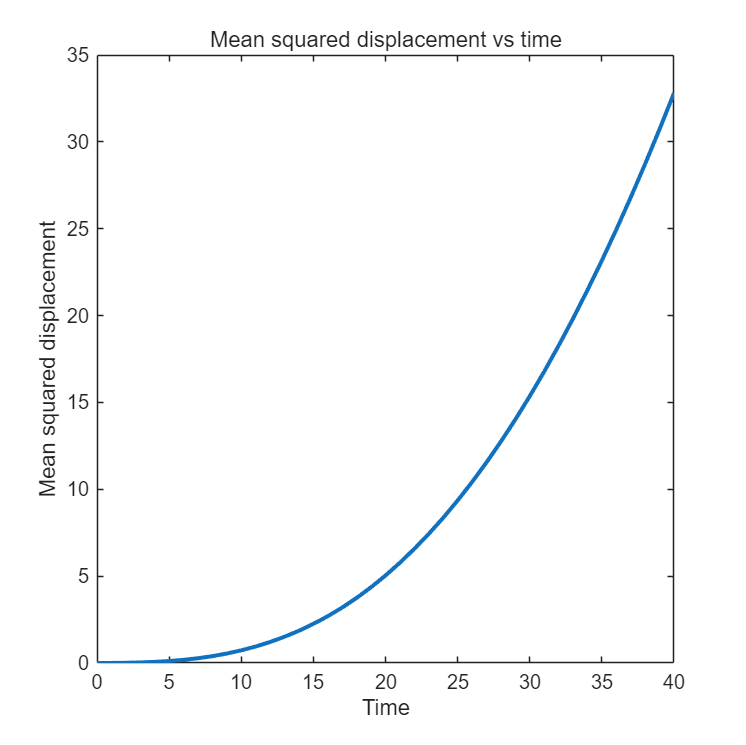


% 统计终点分布
final_x = squeeze(y(end, 1, :));
final_y = squeeze(y(end, 2, :));

% 作图：均方位移随时间
figure;
plot((0:number_of_times)*time_step, r2 / number_of_trajectories, 'LineWidth', 2);
xlabel('Time'); ylabel('Mean squared displacement');
title('Mean squared displacement vs time');

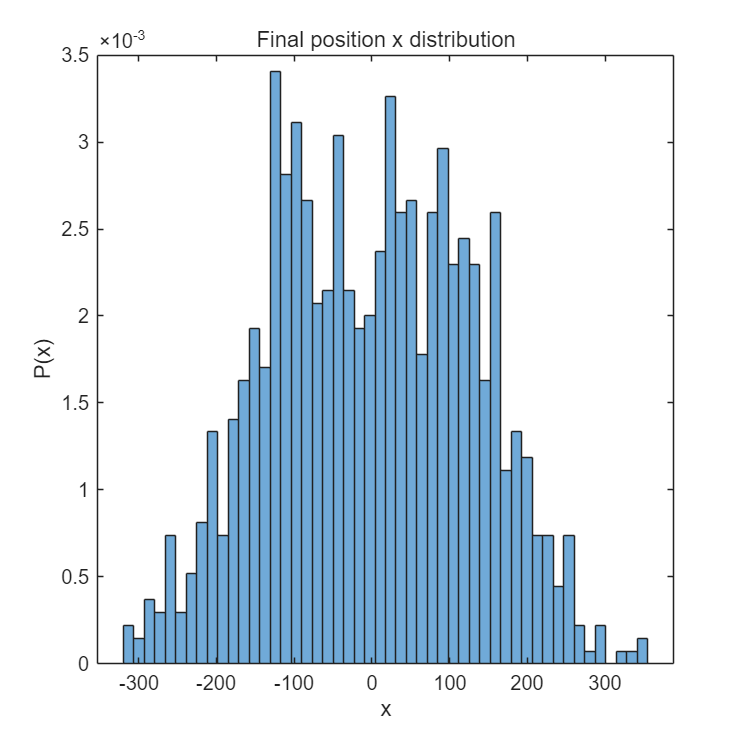


% 统计终点分布并作图（x方向）
figure;
histogram(final_x, number_of_bins, 'Normalization', 'pdf');
xlabel('x'); ylabel('P(x)');
title('Final position x distribution');

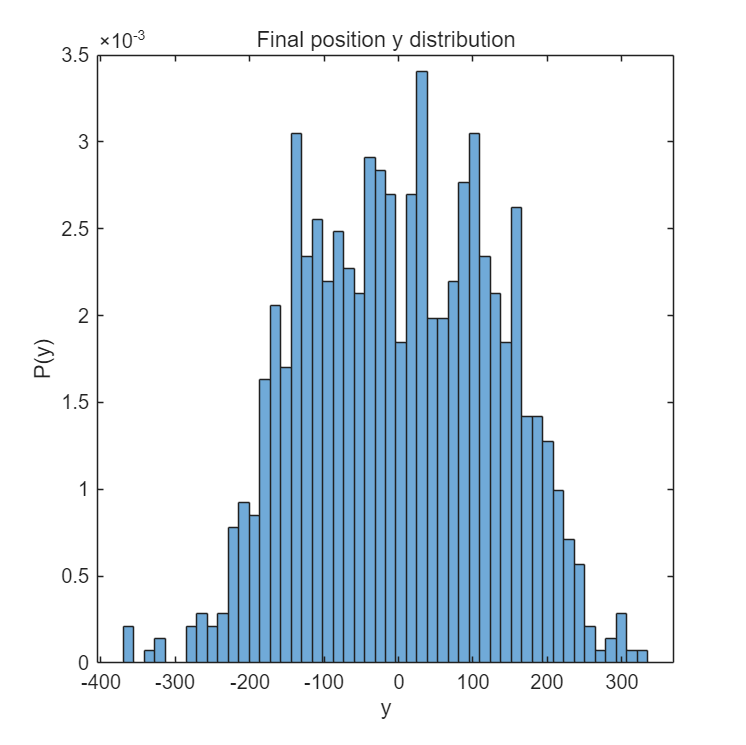


% 统计终点分布并作图（y方向）
figure;
histogram(final_y, number_of_bins, 'Normalization', 'pdf');
xlabel('y'); ylabel('P(y)');
title('Final position y distribution');